# Optimization design of rebar in a Two-Span concrete beam

This figure below shows the rebar design prototype considered for optimization design (search space). A maximum of three different rebar diameter sizes can be placed both at top reinforcement and bottom reinforcement.

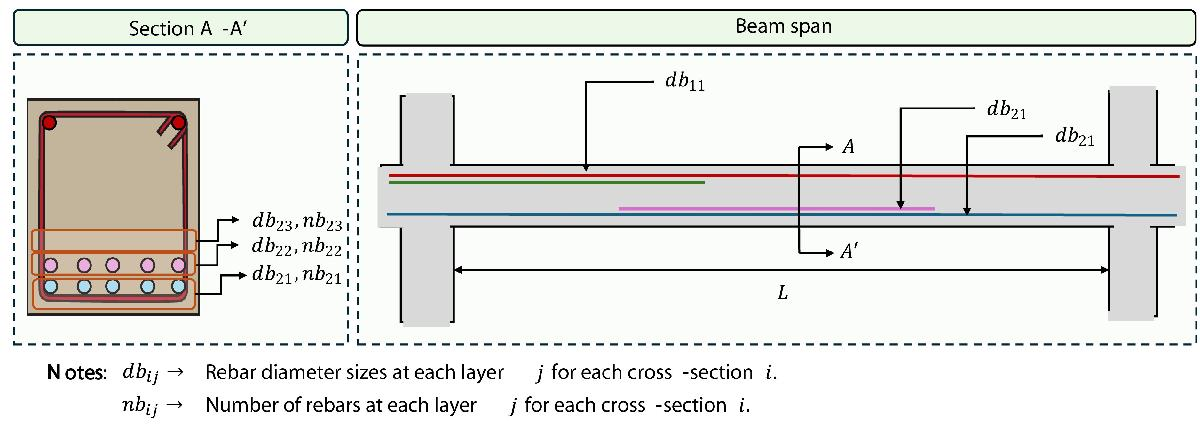

Note: This algorithm does not use any AI model nor enhancement but only plain Meta-heuristics (PSO in this case).

## Insert the folder path to store the rebar design results

Results will be stored as .csv files

directionData='C:\Users\lfver\OneDrive\Desktop\OneDrive\CALDRECUST\Software\Package\Visual_CALDRECUST\Design_Data\RebarBeams\';

% If results are to be saved, input saveResults=true
saveResults=true

saveResults = logical
   1


## Insert geometry of the beam element 

Lv=[4000;5000]; % mm
Totalspan = sum(Lv); % mm

bv=[300;300]; % mm
hv=[600;600]; % mm
        
hrec=50; % 
brec=50; % lateral concrete cover


## Insert material properties

### Concrete

fcuv=[35;35]; % MPa


### Steel reinforcement

fy=500; % Yield stress of steel reinforcement (N/mm2)
wac=7.85e-6; % unit volume weight of the reinforcing steel (Kg/mm3)

## Insert parameters for structural analysis with the FEM

### Create numerical model

% Discretization length
dL=100; % mm

% B.C.
supportsv=[0,4000,9000]; % mm


### Distributed loads 

Wv=[30,30;
    30,30]; % N/mm

Wrange=[0, 4000;
        4000, 9000]; % mm 
    
nspans=length(Wrange(:,1));


## **Analysis is executed**

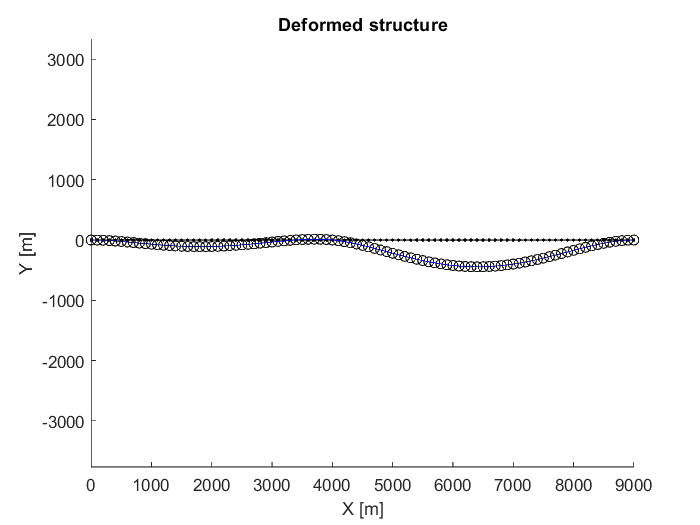

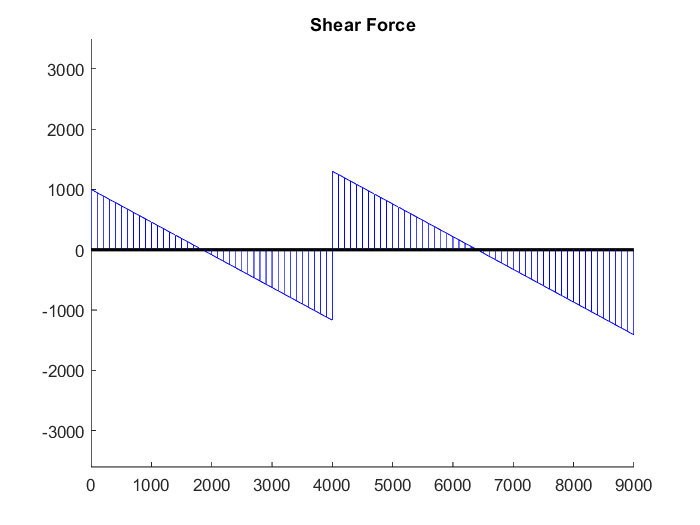

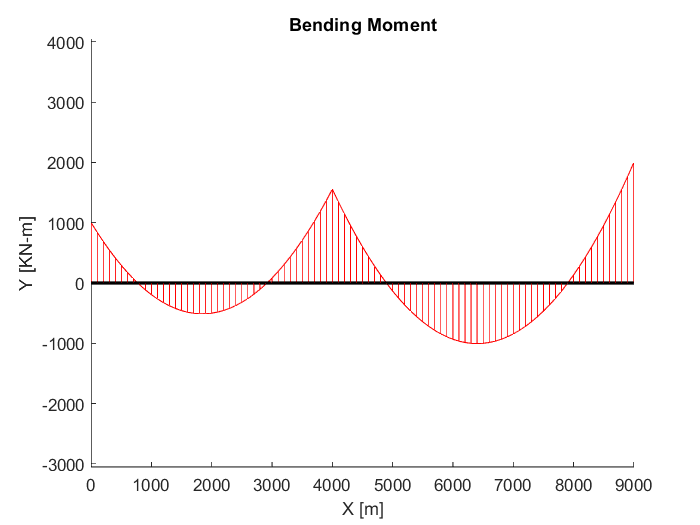

Ac = bv .* hv;
Ic = bv .* hv .^ 3 / 12;
Ec = (3.46 * sqrt(fcuv) + 3.21) .* 1e3;

[R,U,V,M]=MSFSFEMBeams(Totalspan,Ac,Ic,Ec,supportsv,Wv,dL,Wrange,1);

### Results from FEA are processed

The critical bending moments are extracted for the span (three main cross-sections left, mid and right). Based on the locations of these critical bending moments, the location of cuts is calcualted.

ne=zeros(1,nspans);
neSum=0;
load_conditions=[];
cutxLocMSBeams=[];
for i=1:nspans
    
    ne(i)=(supportsv(i+1)-supportsv(i))/dL;
    i1=neSum+1;
    Mleft(i,1)=M(1,i1);
    
    neSum=neSum+ne(i);
    Mright(i,1)=M(1,neSum);
    
    [Mmid(i,1),mp]=max(M(1,i1:neSum));
    load_conditions=[load_conditions;
                    i Mleft(i,1) Mmid(i,1) Mright(i,1)]; %Kg-cm (flexure)
    
    %% Cut location ( local coordinates)
    cutxLocBeam(i,:)=cutLocationSSRecBeam(M(:,i1:neSum),dL);
    cutxLocMSBeams=[cutxLocMSBeams,cutxLocBeam(i,:)];
end

## Rebar data

Aavialable commercial rebar diameters

% Format: [idx, diam (mm)]
rebarAvailable=[1 6;
                2 8;
                3 10;
                4 12;
                5 16;
                6 20;
                7 25;
                8 32;
                9 40
                10 50]; % mm^2

Additional design parameters 

dvs=10; % default diameter size for shear links

%% Maximum and minimum reinforcement percentage area
pmin=0.003;
pmax=0.025;

% Max aggregate size (mm)
hagg=20;

## Optmization design of longitudinal reinforcement

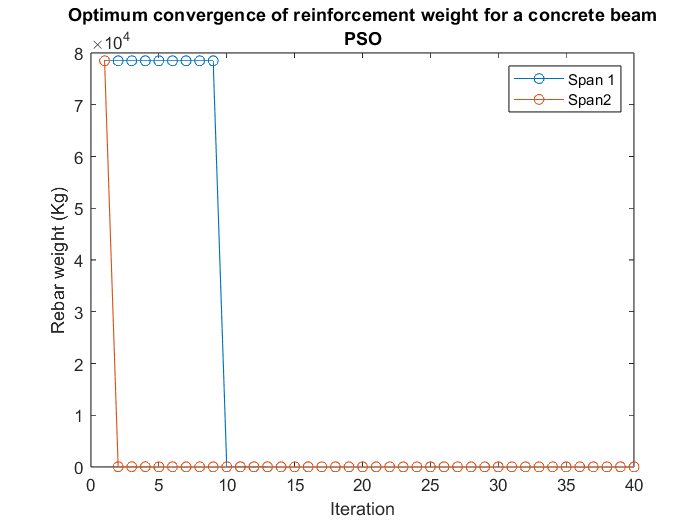

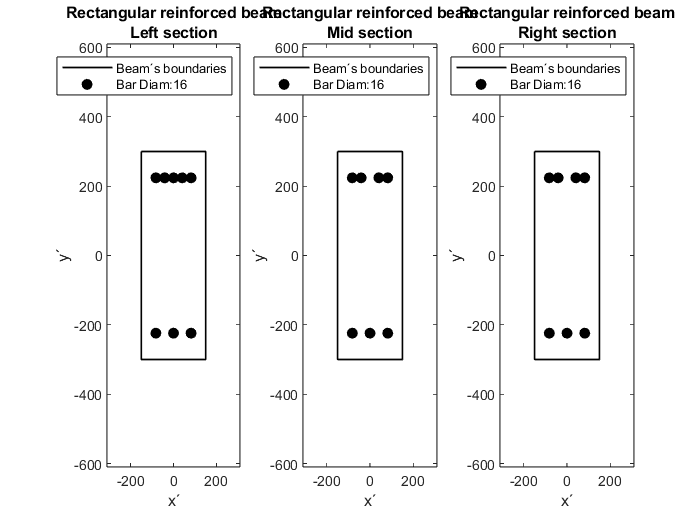

% Constructability weight factors (see documentation)
WUB=[0.6,0.7];
WND=[0.6];
WNB=[0.4];
WNC=[0.6,0.7];
Wcs1=2;
Wcs2=0.5;
WfaConstr=[WUB,WND,WNB,WNC,Wcs1,Wcs2];


[volRebarSpans,LenRebarL,LenRebarM,LenRebarR,sepRebarSpans,db9Spans,EffSpans,...
MrSpans,cSpans,ListRebarDiamLeft,ListRebarDiamMid,ListRebarDiamRight,...
DistrRebarLeft,DistrRebarMid,DistrRebarRight,tenbLMRspan,totnbSpan,...
CFAspans]=OptimMSFSBeamsRebar3DSec(bv,hv,Lv,brec,hrec,hagg,pmin,pmax,...
rebarAvailable([3:10]',:),fcuv,load_conditions,fy,wac,cutxLocBeam,WfaConstr,1,1,...
[1,2],70,40);


if sum(db9Spans)==0
    return;
end

## **Process optimum design results for shear design**

dbLMRMSBeam=[];
ShearDesignMSBeam=[];
tenbLMRMSBeam=[];
totnbSpanMSBeams=[];
neSum=0;
for i = 1: nspans
    i1=neSum+1;
    
    neSum=neSum+ne(i);
    
    dbLMRMSBeam=[dbLMRMSBeam,db9Spans(i,:)];
    
    % Average percentage of cross-section reinforcement 
    rho=sum(tenbLMRspan(i,:).*(db9Spans(i,:).^2*pi/4))./(bv(i)*hv(i))/3;  
    
    % Execute shear design
    [s1(i,1),s2(i,1),s3(i,1),d1(i,1),d2(i,1)]=shearDesignBeams(Lv(i),bv(i),hv(i),...
                                            hrec,fcuv(i),fy,V(1,i1:neSum),dvs,rho);
    ShearDesignMSBeam=[ShearDesignMSBeam,...
                        s1(i,1),s2(i,1),s3(i,1),d1(i,1),d2(i,1),dvs];
    dvsBeams=dvs(1,1);
    
    % Decompose NbSpans matrix of size [ nspans x 9 ] into a vector of
    % size [ 1 x nspans * 9 ]       
    tenbLMRMSBeam=[tenbLMRMSBeam,tenbLMRspan(i,:)];
    totnbSpanMSBeams=[totnbSpanMSBeams,totnbSpan(i,:)];
end
ShearDesignMSBeams{1}=ShearDesignMSBeam;


beamNSb=zeros(nMSbeams,1);

## **Side rebars (if necessary)**

**In case the cross-section height of the beam is larger than 750 mm, then side rebars are provided to mitigate cracks**

if max(hv)>=750
    [dSb,nSb,sepSb,distrSideBars]=sideBarsRecBeams3SecSpan(max(bv),max(hv),fy,...
            brec,hrec,tenbLMRspan,db9Spans,dvs,hagg,rebarAvailable);
    
    beamNSb(1,1)=2*nSb;
    diamlistdSb=zeros(2*nSb,1)+dSb;
    
    plotBeamSideBar3sec(b,h,-DistrRebarLeft,ListRebarDiamLeft,...
            DistrRebarMid,ListRebarDiamMid,-DistrRebarRight,...
            ListRebarDiamRight,diamlistdSb,distrSideBars,nfig);
else
    distrSideBars=[];
    diamlistdSb=[];
end

diamlistdSbMSBeam{1}=diamlistdSb;
distrSbMSBeam{1}=distrSideBars;


## **Export results**

Input the desired file path to save the results to .csv files

if saveResults
    nMSbeams=1;
    eleMSBeams{1}=[1,2];
    NbMSBeams{1}=tenbLMRMSBeam;
    DimMSBeams{1}=[bv',hv',Lv',brec,hrec];
    dbMSBeams{1}=dbLMRMSBeam;
    DecompCutxLocMSBeams{1}=cutxLocMSBeams;
    ListDiamLeftMSBeams{1}=ListRebarDiamLeft;
    ListDiamMidMSBeams{1}=ListRebarDiamMid;
    ListDiamRightMSBeams{1}=ListRebarDiamRight;
    LenRebarLeftMSBeams{1}=LenRebarL;
    LenRebarMidMSBeams{1}=LenRebarM;
    LenRebarRightMSBeams{1}=LenRebarR;
    DistrDiamLeftMSBeams{1}=DistrRebarLeft;
    DistrDiamMidMSBeams{1}=DistrRebarMid;
    DistrDiamRightMSBeams{1}=DistrRebarRight;
    NTotalMSBeams{1}=totnbSpanMSBeams;
    
    ExportDesignMSRecBeam(directionData,nMSbeams,eleMSBeams,DimMSBeams,...
        dbMSBeams,DecompCutxLocMSBeams,DistrDiamLeftMSBeams,DistrDiamMidMSBeams,...
        DistrDiamRightMSBeams,NTotalMSBeams,NbMSBeams,ListDiamLeftMSBeams,...
        ListDiamMidMSBeams,ListDiamRightMSBeams,LenRebarLeftMSBeams,...
        LenRebarMidMSBeams,LenRebarRightMSBeams,diamlistdSbMSBeam,distrSbMSBeam,...
        beamNSb,ShearDesignMSBeams)
end

## **Function appendix**